# Prognostic Health Management

**Name**: 

Kwak, Jin/21900031

Kim, Sunwoo/22000090

**Date**       :2024.10.05

**Modified**:2024.10.12

# Introduction

In this lab, [](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)[AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM) is used to develop a machine learning model for coil defect diagnosis(Hot-Air Process Equipment)

### **Process Description**

Hot-Air Drying Process:

    - Ensures that the film and protective agents adhere stably to the metal surface after plating

    - Completely dries moisture from the product surface.

    - Used in various fields(e.g. electronic component coating, automotive paint processes, and ceramic processes)

    - **Process Defects**

        - High power consumption using coil $\rightarrow$Overheating, Irregular temperature transmission $\rightarrow$Poor product quality/Equipment Fault

        - Coil fault may cause issues with the cooling motor $\rightarrow$ Vibration patterns changes.

The goal is to identify these changes to diagnose the issues early on and prevent equipment failure.

## Goal of the Project

Two separate, distinguishable goals.

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish degradation model

## Specific Goals

1.1) Achieve detection(Normal/Error) accuracy up to 90% 

1.2) Ensure the model performance with Feature Reduction and analyze the feature reduction

2.1) 80% < Probability of Predicted RUL within αbound after Train-Test Breakpoint

## Dataset

Dataset name: [AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)

Data Measurement:

- PLC data(Sampling Period: 5[sec])

- Sound data

Data Categories:

- Numerical data from PLC 

- Sound data:

- Error Lot list

## **Goal of the Project**

Two main goals of the project are introduced in this project. The dataset is originally used for classification. Authors will prepare for a **ML model for fault classification** and **Fault Diagnosis Model(Remaining Useful Life Estimation Model)**

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish **degradation model**

## **Expected Outcome**

**Before: **Difficulty on immediate problem check of coil defects on-site on real-time base

**After: **Quickly respond to equipment fault $\rightarrow$Equipment management, Increase in productivity.

## Schedule

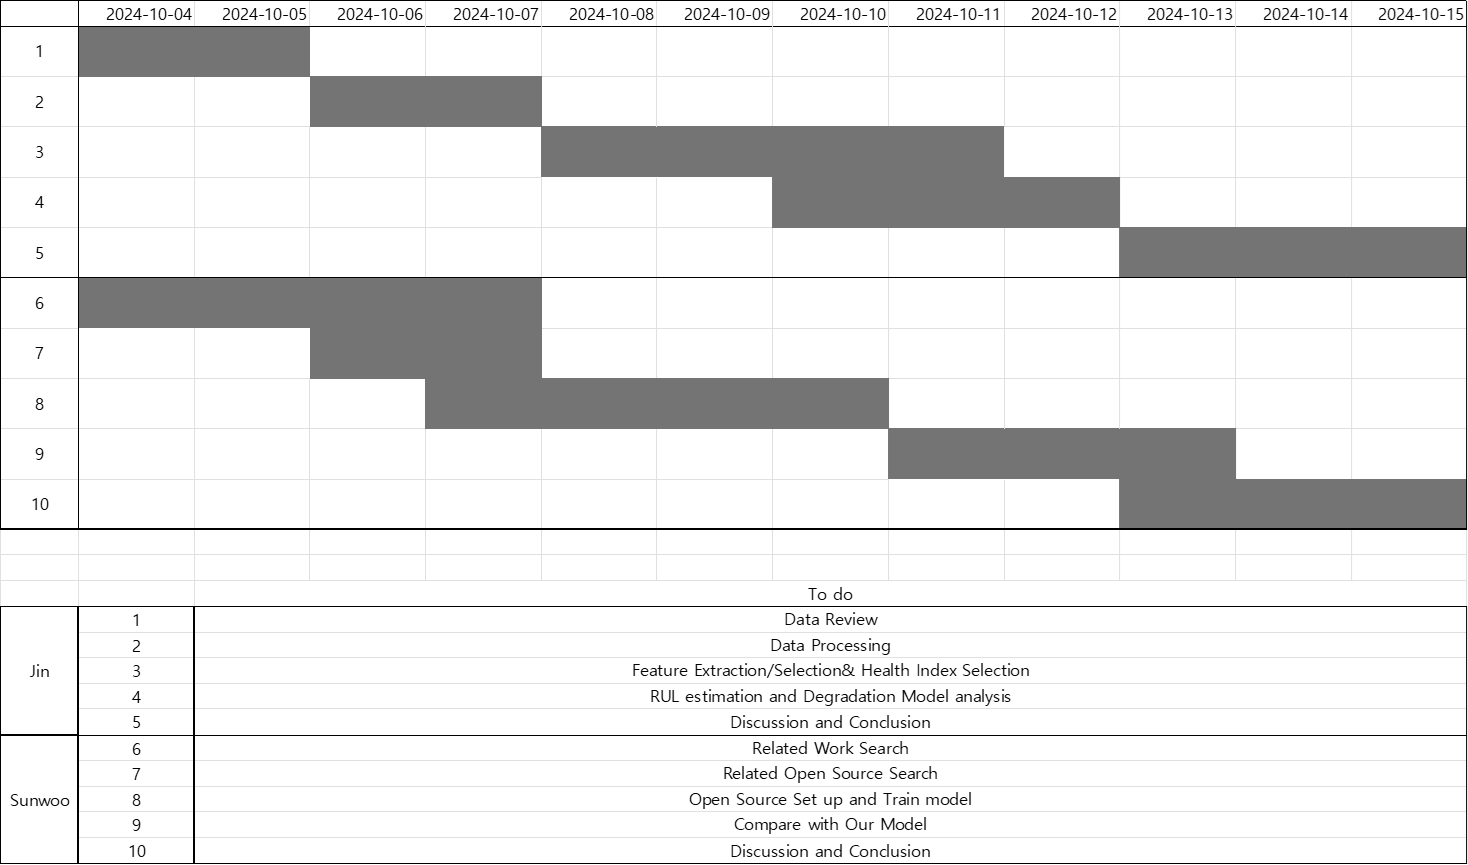

clc; clear all;
addpath("data\FAN_sound_error\");
addpath("data\FAN_sound_OK\")   ;
addpath("data\5공정_180sec\")   ;

**Import Sound Data **

N_sound_error = 13                               ;
N_sound_normal= 170                              ;
error_sound_filename  = "FAN_sound_error_0%d.wav";
normal_sound_filename = "FAN_sound_0%d.wav"      ;
for idx = 1:9
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end
error_sound_filename = "FAN_sound_error_%d.wav"  ;
normal_sound_filename= "FAN_sound_%d.wav"        ;
for idx = 10:13
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
end
for idx = 10:N_sound_normal
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end

**Import PLC data**

Unfortunately, the time-series data is not strictly real-time, in which means that this data is collected every 5 seconds approximately.

day   = [6:10,13:17,23,24,27:30,1,5:8,12:15,18:22,25:27];
month = [9*ones(1,16),10*ones(1,17)];
dates = datetime(2021,month,day,'Format','uuuu.MM.dd');
txt_form = "kemp-abh-sensor-%s.csv";
for idx = 1:length(day)
    file_name    = sprintf(txt_form,dates(idx));
    data_temp    = readmatrix(file_name) ; 
    plc_data{idx}= data_temp(:,[1,2,4,5]); 
end


**Data Enumeration**

Cell data will be in time-series and each features are grouped by a struct.

% Enumerations
IDX      = 1  ;
PROCESS  = 2  ;
TEMP     = 3  ;
CURRENT  = 4  ;
CLASS    = 5  ;
% For cell data
RAW_DATA = 1  ;
MAX_FREQ = 2  ;
FEAT     = 3  ;


**The sound data** is very similar to the vibration data as it has amplitude and frequency. Time and frequency features are to be extracted for the data analysis.

However, the sound data is subdivided into normal/error which means this should be only used as classification not RUL. Only possible if the sound data can be collected on real-time

for idx = 1 : N_sound_error
    sound_error{idx,3} = get_features(sound_error{idx,1});
end
for idx = 1 : N_sound_normal
    sound_normal{idx,3} = get_features(sound_normal{idx,1});
end

Compare time-domain sound data of normal/error

idx = 13;

ex_sound_error = sound_error {idx,RAW_DATA}(:,1);
ex_sound_normal= sound_normal{idx,RAW_DATA}(:,1);
time = 0:1/sound_error{idx,MAX_FREQ}:(length(ex_sound_error)-1)/Fs;

figure;
subplot(2,1,1); hold on;
title('Sound data(Error)','FontWeight','bold');
plot(time, ex_sound_error);grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
time = 0:1/sound_normal{idx,MAX_FREQ}:(length(ex_sound_normal)-1)/Fs;
ylim([-0.15 0.15]);
subplot(2,1,2); hold on;
title('Sound data(Normal)','FontWeight','bold');
plot(time, ex_sound_normal); grid on           ;
xlabel('Time [s]'); ylabel("Amplitude [-]")    ;
ylim([-0.15 0.15]);
Fs = 44100;  %Hz
figure;
[freq, amp_normal] = get_fft(ex_sound_normal,Fs);
[freq, amp_error]  = get_fft(ex_sound_error,Fs);
figure;
subplot(2,1,1); hold on; grid on;
plot(freq,amp_normal); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Normal)');ylim([0 0.02]); xlim([0 1e4]);
subplot(2,1,2); hold on; grid on;
plot(freq,amp_error); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Error)');ylim([0 0.02]); xlim([0 1e4]);

To further illustrate the frequency features of normal/error data, `get_freq_features()` function is used.

normal_frequency_features = get_freq_features(amp_normal,Fs)
error_frequency_features  = get_freq_features(amp_error,Fs)

Each time features, frequency features are collected and averaged. They are plotted as below

First few sample data time features plot. This shows that error sound is very random and shows inconsistent values of all features.

feature_names =["rms" "sra" "aav" "energy" "peak" "ppv" "if" "sf" "cf" "mf" "sk" "kt" "fft"];
figure;
for idx = 1:(length(feature_names)-1)
    avg(idx,1) = get_average_feature(sound_error ,feature_names(idx))       ;
    avg(idx,2) = get_average_feature(sound_normal,feature_names(idx))       ;
    error_features(:,idx)= get_all_feature(sound_error ,feature_names(idx)) ;
    normal_features(:,idx)= get_all_feature(sound_normal,feature_names(idx));
    subplot(3,4,idx); hold on; grid on           ;
    plot(error_features(:,idx),'r-')             ; 
    plot(normal_features(1:13,idx),'b-')         ;
    legend('Error','Normal')                     ;
    legend('Location','best')                    ;
    xlabel('Sample index','FontSize',7)          ;
    title(feature_names(idx),'FontWeight','bold');
end

# Data Preprocessing

## error data processing

% temperture / current 값에 대해서 error 별로 feature 뽑기
% PLC time-domain analysis

N_plc = 33;
Fs = 1.0 /5.0;
for idx = 1 : N_plc
    temp = plc_data {idx};
    plc_current{idx,1}  = temp(:,3);
    plc_current{idx,2}  = Fs;
    plc_current{idx,3}  = get_features(plc_current{idx,1});
    plc_temperature{idx,1}= temp(:,4);
    plc_temperature{idx,2}= Fs;
    plc_temperature{idx,3}= get_features(plc_temperature{idx,1});
end


error_list = readmatrix("Error Lot list.csv");
error_list = error_list(2:end,2:end);
if exist("var_names")
    clear var_names;
end
if exist("var_types")
    clear var_types;
end
for idx =1:length(error_list(1,:))
    var_names(idx) = sprintf("Error%d",idx);
end
var_names  = ["datetime" var_names];
error_names= var_names(2:end);

var_types(1,1:11) = "double";

var_types = ["datetime" var_types];
size_error_list =size(error_list);
size_error_list(2) = size_error_list(2)+1;
error_table= table('Size',size_error_list,'VariableTypes',var_types,'VariableNames',var_names);
error_table.datetime = dates';
for row = 1:length(error_list(:,1))
    for col = 1:length(error_list(1,:))
        if isnan(error_list(row,col))
            error_list(row,col) = 0;
        end
    end
end
error_table(:,2:end) = array2table(error_list);

% Sort by error
for row = 1:length(plc_data)
    temp_plc_data      = plc_data{row};
    temp_plc_data(:,5) = 0;
    for col= 1:length(error_list(1,:))
        if error_list(row,col) ~= 0
            indices = find(temp_plc_data(:,2) == error_list(row,col));
            temp_plc_data(indices,5) = col;
        end
    end
    plc_data{row} = temp_plc_data;
end


# Feature extraction

train data 와 test data 나누기

rng(0);
cv = cvpartition(length(day), 'Holdout', 0.2);
test_idx = cv.test;
test_idx(16,1) = 0;
cnt_test = 1;
cnt_train= 1;
% Each cell is test/train dataset.
% Each column represents number of process, current or temperature, and
% classification respectively
for idx = 1:length(day)
        PLC_current{idx}                = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        PLC_temperature{idx}            = plc_data{idx}(:,[PROCESS TEMP CLASS]);
    if test_idx(idx)
        test_current{cnt_test}     = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        test_temperature{cnt_test} = plc_data{idx}(:,[PROCESS TEMP CLASS]);
        cnt_test = cnt_test + 1;
    else
        train_current{cnt_train}     = plc_data{idx}(:,[PROCESS CURRENT CLASS]);
        train_temperature{cnt_train} = plc_data{idx}(:,[PROCESS TEMP CLASS]);
        cnt_train= cnt_train + 1;
    end
end

train & test featrue

% TODO Get features of each process

for idx_day = 1:length(PLC_current)
    PLC_current_day = PLC_current{idx_day};
    PLC_temperature_day = PLC_temperature{idx_day};
    process = 1;
    start_idx = 1;

    for idx_time = 1:length(PLC_current_day)
        if PLC_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            PLC_feature(idx_feature) = get_features_plc(PLC_temperature_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,3)) ;
            process = PLC_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        
        if PLC_current_day(idx_time,1) == 43
            end_idx = length(PLC_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            PLC_feature(idx_feature) = get_features_plc(PLC_temperature_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,2), PLC_current_day(start_idx:end_idx,3)) ;
        end
        
    end

end

for idx_day = 1:length(train_current)
    train_current_day = train_current{idx_day};
    train_temperature_day = train_temperature{idx_day};
    process = 1;
    start_idx = 1;

    for idx_time = 1:length(train_current_day)
        if train_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            train_feature(idx_feature) = get_features_plc(train_temperature_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,3)) ;
            process = train_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        
        if train_current_day(idx_time,1) == 43
            end_idx = length(train_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            train_feature(idx_feature) = get_features_plc(train_temperature_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,2), train_current_day(start_idx:end_idx,3)) ;
        end
        
    end

end

for idx_day = 1:length(test_current)
    test_current_day = test_current{idx_day}(:,[1 2 3]);
    test_temperature_day = test_temperature{idx_day}(:,[1 2 3]);
    process = 1;
    start_idx = 1;
    
    for idx_time = 1:length(test_current_day)
    
        if test_current_day(idx_time,1) ~= process  
            end_idx = idx_time - 1;
            idx_feature = process + (43 * (idx_day - 1));
            test_feature(idx_feature) = get_features_plc( test_temperature_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,3)) ;          
            process = test_current_day(idx_time,1);
            start_idx = idx_time ;
        end
        
        if test_current_day(idx_time,1) == 43
            end_idx = length(test_current_day);
            idx_feature = process + (43 * (idx_day - 1));
            test_feature(idx_feature) = get_features_plc( test_temperature_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,2), test_current_day(start_idx:end_idx,3)) ;
        end
        
    end

end

# Feature Selection/Reduction

% error 별로 뽑은 feature 들을 feature selectoin 후 featuer reduction을 통해서 feature
% 정하기 temp / current 별로 구분
filed = struct2table(train_feature);
train_data = table2array(filed(:,1:28));
error = table2array(filed(:,"error"));

PLC_data_2 = struct2table(PLC_feature) ;
PLC_data = table2array(PLC_data_2(:,1:28)) ;
Y = table2array(PLC_data_2(:,29)) ;

if exist("X")
    clear X
end
N_feature = 28;
N_select  = 15;
idx_min   = 1;
errorRate_min = ones(1,N_select);
select_mat = zeros(1,N_feature);

for idx_1 = 1:N_select
    for idx_2 = 1:N_feature
        if select_mat(idx_2)
            continue;
        end
        X(:,idx_1) = PLC_data(:,idx_2);
        mdl  = fitcecoc( X , Y );
        errorRate = loss(mdl, X, Y, 'LossFun', 'classiferror');
        if errorRate < errorRate_min(idx_1)
            errorRate_min(idx_1) = errorRate ;
            idx_min = idx_2 ;
        end
    end
    select_mat(idx_min) = 1;
    X(:,idx_1) = PLC_data(:,idx_min)
end
est_accuracy = 1-errorRate_min;

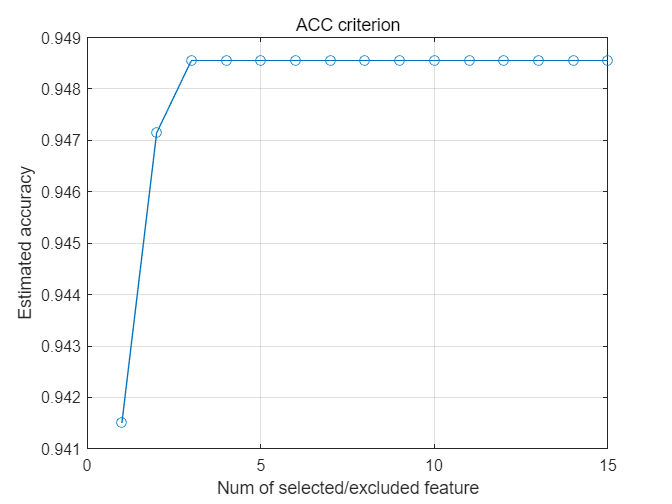

figure
plot(est_accuracy, '-o'); title("ACC criterion");   grid on;
xlabel("Num of selected/excluded feature"); ylabel("Estimated accuracy");

select = table2array(struct2table(load("select.mat")));

# Classification

classLabels = categorical([0 , 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11]);
X_mdl = PLC_data(:,select==1);

% SVM 기반 ECOC 학습 / current

cl = fitcecoc(X_mdl, Y, 'Learners', templateSVM('KernelFunction', 'rbf'), ...
              'ClassNames', classLabels, 'Coding', 'onevsall', 'Verbose', 1)

111개의 음성 관측값과 1308개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 1(SVM)을(를) 훈련시키는 중입니다.
1396개의 음성 관측값과 23개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 2(SVM)을(를) 훈련시키는 중입니다.
1396개의 음성 관측값과 23개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 3(SVM)을(를) 훈련시키는 중입니다.
1398개의 음성 관측값과 21개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 4(SVM)을(를) 훈련시키는 중입니다.
1406개의 음성 관측값과 13개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 5(SVM)을(를) 훈련시키는 중입니다.
1407개의 음성 관측값과 12개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 6(SVM)을(를) 훈련시키는 중입니다.
1410개의 음성 관측값과 9개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 7(SVM)을(를) 훈련시키는 중입니다.
1416개의 음성 관측값과 3개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 8(SVM)을(를) 훈련시키는 중입니다.
1416개의 음성 관측값과 3개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 9(SVM)을(를) 훈련시키는 중입니다.
1417개의 음성 관측값과 2개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 10(SVM)을(를) 훈련시키는 중입니다.
1418개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 11(SVM)을(를) 훈련시키는 중입니다.
1418개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 12(SVM)을(를) 훈련시키는 중입니다.


cl =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1    2    3    4    5    6    7    8    9    10    11]
           ScoreTransform: 'none'
           BinaryLearners: {12×1 cell}
               CodingName: 'onevsall'


  Properties, Methods


ErrorRate = loss(cl, X_mdl, Y, 'LossFun', 'classiferror');
accuracy = 1-ErrorRate

accuracy =          0.997181113460183


Xtest_2 = struct2table(test_feature);
Xtest_1 = table2array(Xtest_2);
Xtest   = Xtest_1(:,select == 1)

Xtest =           70.9545969985313          71.0311294935523          70.9166931915602          77.8771039577811          12.3434403655415
          70.9992275161293          71.0738772715173          70.9620507884587          77.9081485396546          13.7041135394963
          70.5794908315443          70.6669852304023          70.5359857584263          77.4995794078725          13.4575962555545
          71.2054535865061          71.2709746082266          71.1728376756865          77.5864344055193          12.3025702192323
          71.1250787192739           71.231232777711          71.0728909846749          83.6537525059191          18.8105777711204
          70.4136178084235          70.5093688297876          70.3655014908476          77.0451851035761          13.0342465331315
          70.7734955626744          70.8454726468465          70.7373658470351          76.5336635922396          12.3403273054377
          71.0382656604689          71.1208548142032          70.9972632304

Ytest = Xtest_1(:,29);

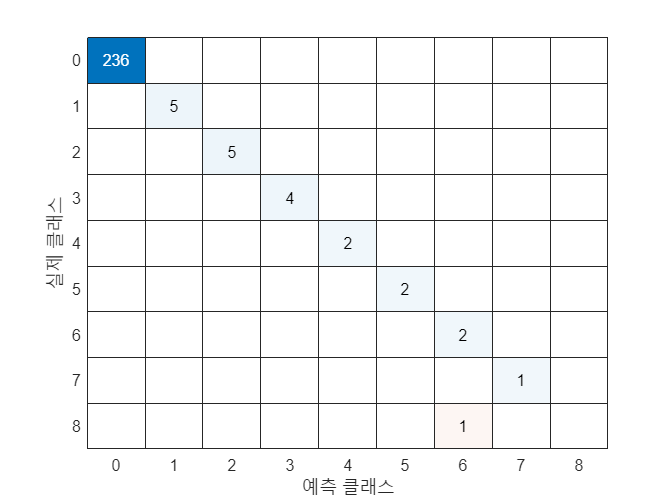

mlClass = predict(cl,Xtest);
mlClass_double = double(string(mlClass));
figure
ldaResubCM = confusionchart(Ytest,mlClass_double);

% knn model




Top 4 important features selection

% FI                = featureImportance{:,:} > 0.5;
% trainData         = struct2table(train_feature);
% trainDataSelected = trainData(:, FI)
% meanTrain = mean(trainDataSelected{:,:});
% sdTrain   = std(trainDataSelected{:,:});
% trainDataNormalized = (trainDataSelected{:,:} - meanTrain)./sdTrain;
% coef = pca(trainDataNormalized);
% 
% PCA1 = (trainDataSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
% PCA2 = (trainDataSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);
% 
% figure
% numData = size(featureTable, 1);
% scatter(PCA1, PCA2, [], 1:numData, 'filled')
% xlabel('PCA 1')
% ylabel('PCA 2') 
% cbar = colorbar;
% ylabel(cbar, ['Time (' day ')'])


# Validation

# Fault Monitoring and Warning

# RUL Estimation

# Discussion

# Conclusion

**Functions**

function xfeature = get_features(x)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));
end

function xfeature = get_features_plc(x_t,x_c,y)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x_t);
N_Y= length(y);

xfeature.tem_mean     =mean(x_t);
xfeature.tem_std      =std(x_t);
xfeature.tem_rms      =sqrt(sum(x_t.^2)/N);
xfeature.tem_sra      =(sum(sqrt(abs(x_t)))/N).^2;
xfeature.tem_aav      =sum(abs(x_t))/N;
xfeature.tem_energy   =sum(x_t.^2);
xfeature.tem_peak     =max(x_t);
xfeature.tem_ppv      =peak2peak(x_t);
xfeature.tem_if       =xfeature.tem_peak/xfeature.tem_aav;
xfeature.tem_sf       =xfeature.tem_rms/xfeature.tem_aav;
xfeature.tem_cf       =xfeature.tem_peak/xfeature.tem_rms;
xfeature.tem_mf       =xfeature.tem_peak/xfeature.tem_sra;
xfeature.tem_sk       =skewness(x_t);
xfeature.tem_kt       =kurtosis(x_t);

xfeature.cur_mean     =mean(x_c);
xfeature.cur_std      =std(x_c);
xfeature.cur_rms      =sqrt(sum(x_c.^2)/N);
xfeature.cur_sra      =(sum(sqrt(abs(x_c)))/N).^2;
xfeature.cur_aav      =sum(abs(x_c))/N;
xfeature.cur_energy   =sum(x_c.^2);
xfeature.cur_peak     =max(x_c);
xfeature.cur_ppv      =peak2peak(x_c);
xfeature.cur_if       =xfeature.cur_peak/xfeature.cur_aav;
xfeature.cur_sf       =xfeature.cur_rms/xfeature.cur_aav;
xfeature.cur_cf       =xfeature.cur_peak/xfeature.cur_rms;
xfeature.cur_mf       =xfeature.cur_peak/xfeature.cur_sra;
xfeature.cur_sk       =skewness(x_c);
xfeature.cur_kt       =kurtosis(x_c);

% p1 = fft(x);
% p1(2:end-1)= 2.0 * p1(2:end-1); 
% xfeature.fft = p1;
% xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));

xfeature.error = sum(y)/N_Y;
end

function xfeature = get_features_temperature(x,y)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
N_Y= length(y);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));

xfeature.error = sum(y)/N_Y;
end

%%

function average_feature = get_average_feature(x,feature_name)
% Input: the whole cell
    FEATURES =3;
    N = length(x);
    feature = 0.0;
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        feature = feature + val(1);
    end
    average_feature = feature/N;
end

%%
function vectors = get_all_feature(x,feature_name)
% Input: whole cell
    FEATURES =3;
    N = length(x);
    vectors = [];
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        vectors = [vectors; val(1)]; 
    end
end

%%
function [frequency , Amplitude] = get_fft(data,Fs)
% Input : data: Time-series data
%         Fs  : Sampling Frequency
% Output: frequency: Frequency Domain(Bound)
%         Amplitude: Corresponding amplitude of fft data to the frequency
    N = length(data);
    frequency = 0.0:Fs/N:Fs/2;
    fft_data = abs(fft(data)/N);
    fft_data = fft_data(1:floor(N/2)+1);
    fft_data(2:end-1) = 2*fft_data(2:end-1);
    Amplitude = fft_data;
end

%%
function frequency_features = get_freq_features(fft_data, Fs)
% Input  fft_data: fft amplitude data
%        Fs: sampling frequency
% Output frequency_features: table for frequency features. 
    N = length(fft_data);
    frequency_features = table;
    frequency_features.max_amplitude     = max(fft_data);
    frequency_features.frequency_of_max_amplitude = (find(fft_data == max(fft_data))-1)*Fs/N;
    frequency_features.DC_value = fft_data(1);
end
%%



## Reference

[1] (주) KEMP, *Innozinc**세라믹 아연도금**,* [http://kempkorea.com/](http://kempkorea.com/) 

[2] Rauber, Thomas W., Francisco de Assis Boldt, and Flavio Miguel Varejao. "Heterogeneous feature models and feature selection applied to bearing fault diagnosis." *IEEE Transactions on Industrial Electronics* 62.1 (2014): 637-646.

[3] Toliyat, Hamid A., et al. *Electric machines: modeling, condition monitoring, and fault diagnosis*. CRC press, 2017.

[4] 